# E8

#### Matching de figures

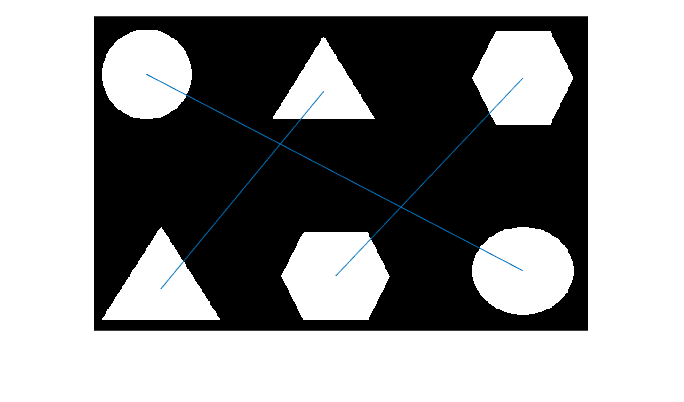

BW = rgb2gray(imread("figures.png")) < 200;
imshow(BW);

% Objectiu: trobar quines lletres es corresponen
BWU = BW; BWU(end/2:end, :) = 0;
%imshow(BWU);
BWD = BW; BWD(1:end/2, :) = 0;
%imshow(BWD);

CCU = bwconncomp(BWU);
CCD = bwconncomp(BWD);

propsU = regionprops('table', CCU, 'Centroid', 'BoundingBox', 'Circularity');

propsD = regionprops('table', CCD, 'Centroid', 'BoundingBox', 'Circularity');

NumObj = CCU.NumObjects;

% Features
%FU = propsU.BoundingBox(:,3)./propsU.BoundingBox(:,4); % amplada/alçada
%FD = propsD.BoundingBox(:,3)./propsD.BoundingBox(:,4); % features
FU = [propsU.Circularity];
FD = [propsD.Circularity];

% normalitzem per columnes segons el seu valor maxim
FU = FU./max(FU);
FD = FD./max(FD);

Assig = dsearchn(FD, FU);

hold on
for i = 1:NumObj
    line([propsU.Centroid(i,1) propsD.Centroid(Assig(i),1)], [propsU.Centroid(i,2), propsD.Centroid(Assig(i),2)])
end
hold off

#### Matching de lletres

clearvars
BW = rgb2gray(imread("Abecedari.png")) < 200;
imshow(BW);
% Objectiu: trobar quines lletres es corresponen
BWU = BW; BWU(end/2:end, :) = 0;

%imshow(BWU);
BWD = BW; BWD(1:end/2, :) = 0;

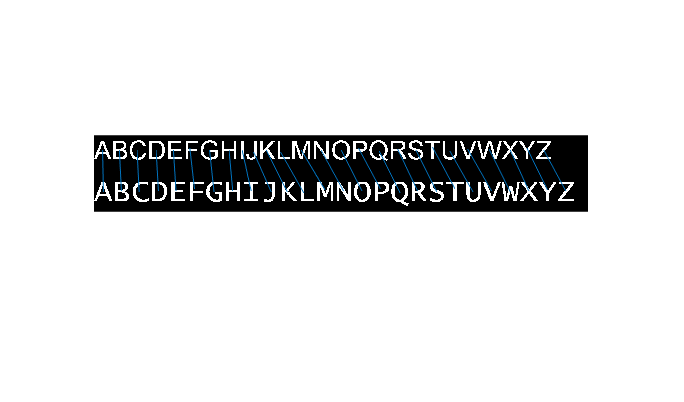

%imshow(BWD);

CCU = bwconncomp(BWU);
CCD = bwconncomp(BWD);

propsU = regionprops('table', CCU, 'Centroid', 'BoundingBox', 'Circularity', 'EulerNumber', 'Eccentricity');

propsD = regionprops('table', CCD, 'Centroid', 'BoundingBox', 'Circularity', 'EulerNumber', 'Eccentricity');

NumObj = CCU.NumObjects;

% Features
%FU = propsU.BoundingBox(:,3)./propsU.BoundingBox(:,4); % amplada/alçada
%FD = propsD.BoundingBox(:,3)./propsD.BoundingBox(:,4); % features
FU = [propsU.EulerNumber];
FD = [propsD.EulerNumber];

% normalitzem per columnes segons el seu valor maxim
FU = FU./max(FU);
FD = FD./max(FD);

A = zeros(NumObj, NumObj);
for i = 1: NumObj
    for j = 1: NumObj
        A(j,i) = norm(FU(i,:) - FD(j,:));
    end
end

Assig = zeros([NumObj 1]);

% realitzem l'aparellament i eliminem els candidats aparellats
for k = 1:NumObj
    [Amins, idx] = min(A); % minims de cada columna i la fila
    [Amins, Ai] = min(Amins);
    Aj = idx(Ai);
    Assig(Ai) = Aj;
    A(Aj,:) = Inf;
    A(:,Ai) = Inf;
end

%Assig = dsearchn(FD, FU);

hold on
for i = 1:NumObj
    line([propsU.Centroid(i,1) propsD.Centroid(Assig(i),1)], [propsU.Centroid(i,2), propsD.Centroid(Assig(i),2)])
end
hold off

#### Transformada de Fourier

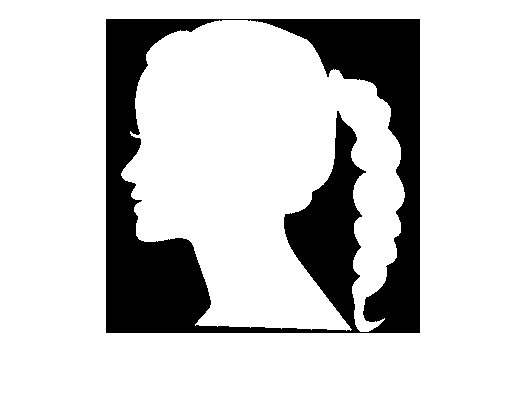

clearvars
im = imread("head.png");
im = imresize(im, 0.5);
imshow(im);

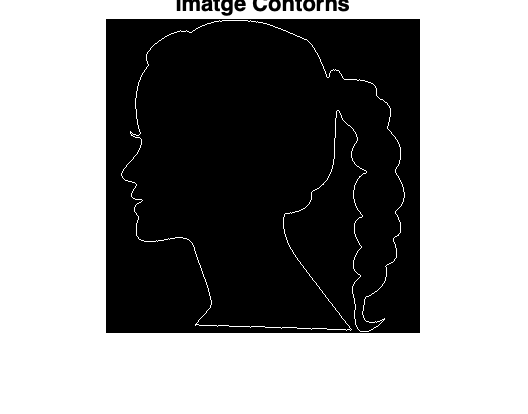


% contorns exteriors
cont = xor(im, imerode(im, strel('disk', 1)));
figure, imshow(cont), title('Imatge Contorns')

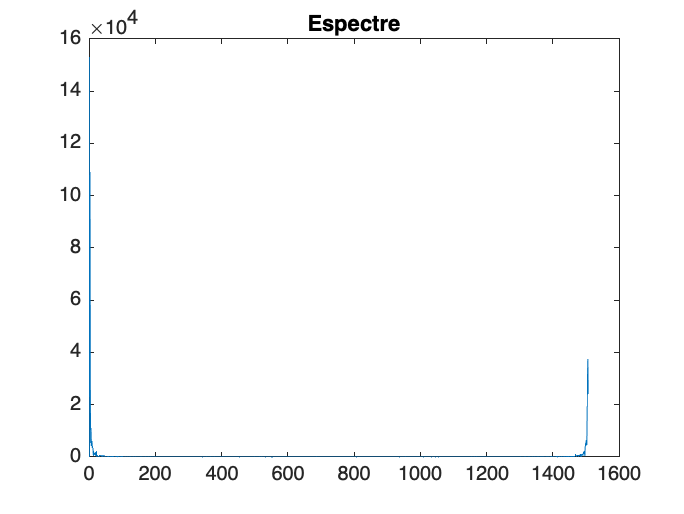

[fila, col] = find(cont, 1);
B = bwtraceboundary(cont, [fila col], 'E');

% coordenades centrades 
mig = mean(B);
Bc = B - mig; % traslladem a l'origen
s = Bc(:,1) + Bc(:,2) *1i; % passem a complexes
% transformada de fourier
z = fft(s);
figure, plot(abs(z)), title('Espectre');

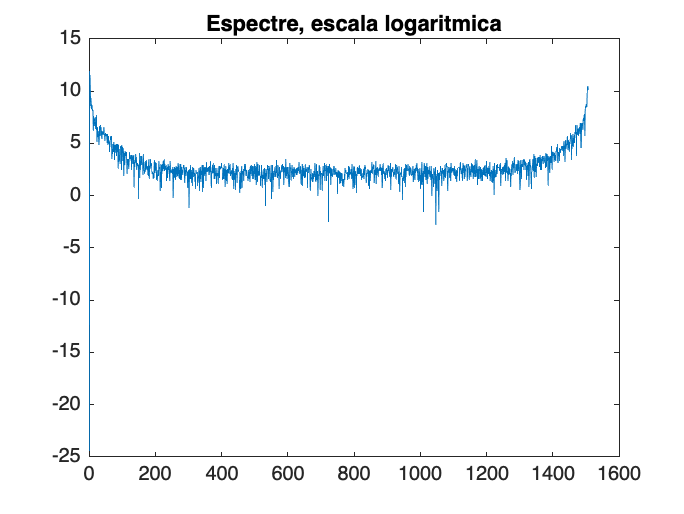

figure, plot(log(abs(z))), title('Espectre, escala logaritmica');

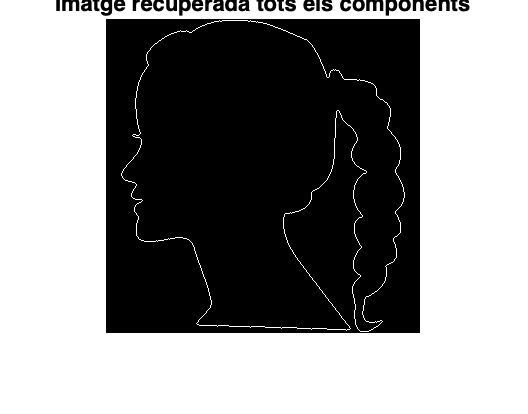


% transformada inversa de fourier
ss = ifft(z);
aux = zeros(size(im));
files = round(real(ss) + mig(1)); % obtenim les coordenades i tornem a situar al centre de la imatge
cols = round(imag(ss) + mig(2));
aux(sub2ind(size(aux), files, cols)) = 1; % posa els pixels de ss a 1
figure, imshow(aux), title('Imatge recuperada tots els components')

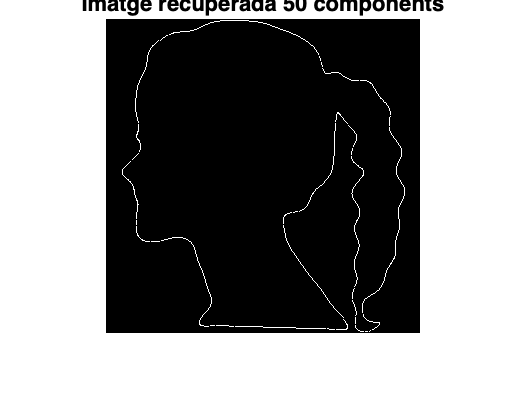


N = 50; % ens quedarem amb N components
zz = z;
% Ens quedem les N primeres i les N últimes
zz(N+1:end-N) = 0; % eliminem a partir dels N components
ss = ifft(zz);
aux = zeros(size(im));
files = round(real(ss) + mig(1)); % obtenim les coordenades i tornem a situar al centre de la imatge
cols = round(imag(ss) + mig(2));
aux(sub2ind(size(aux), files, cols)) = 1; % posa els pixels de ss a 1
figure, imshow(aux), title('Imatge recuperada 50 components')

% Descriptor
desc = abs(zz(1:N));
